## Data Generation for Sine Wave Synthesis.

Jack Kenney, 2018.

BINDS Lab, Computer Science Department, UMass Amherst.

% Randomization Housekeeping
rng(42)
% Defining Parameters
training_sets = 19;
test_sets = 1;
freq_order = 10;
duration_order = 10;
quality = 100;
sets = training_sets + test_sets

sets = 20

file_name = 'data/waves_' + string(sets) + '_' + string(quality)

file_name = "data/waves_20_100"

graphs = true;

max_points = quality*duration_order;
input_data = zeros([sets, max_points, 2]); % 2 = freq,dur
output_data = zeros([sets, max_points]);  % sin wave values
sample_lengths = zeros([sets,1]);
parfor set = 1:sets
    % choose random duration & frequency
    freq = rand() * freq_order  % hertz
    duration = rand() * duration_order  % seconds
    points = floor(quality .* duration)
    sample_lengths(set) = points
    input_values = [ones(points,1)*freq, ones(points,1)*duration] % [[[freq], [duration]]] .* points % (points, 2)
    input_values = [input_values; zeros(max_points-points,2)] % pad end
    % generate x values such that there are quality points per second
    x_values = [0:points-1] ./ quality
    y_values = sin(x_values * (2 * pi * freq))'
    y_values = [y_values; zeros(max_points-points,1)] % pad end
    input_data(set,:,:) = input_values
    output_data(set,:) = y_values
end

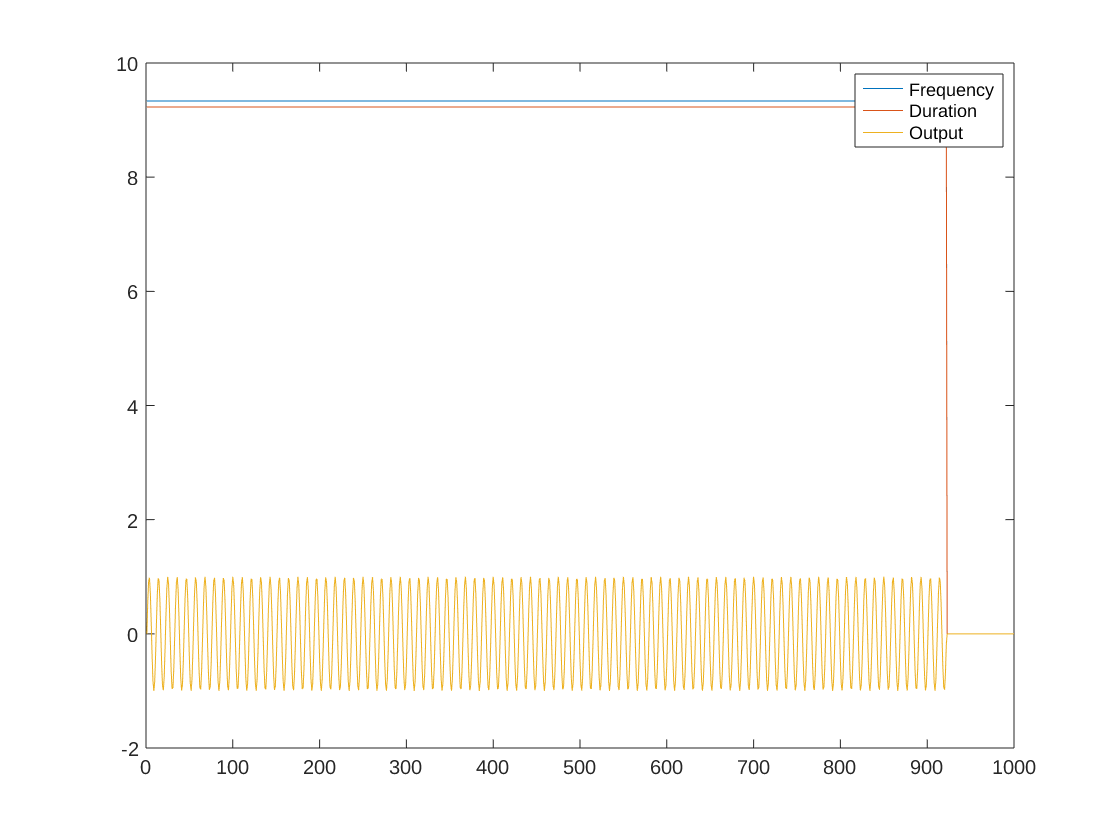

if graphs
    plot(input_data(1,:,1))
    hold on
    plot(input_data(1,:,2))
    plot(output_data(1,:))
    legend(["Frequency","Duration","Output"])
    hold off
end

save(file_name, 'input_data', 'output_data', 'sample_lengths')